# Equipe Taranis : Hackathon AI4IA

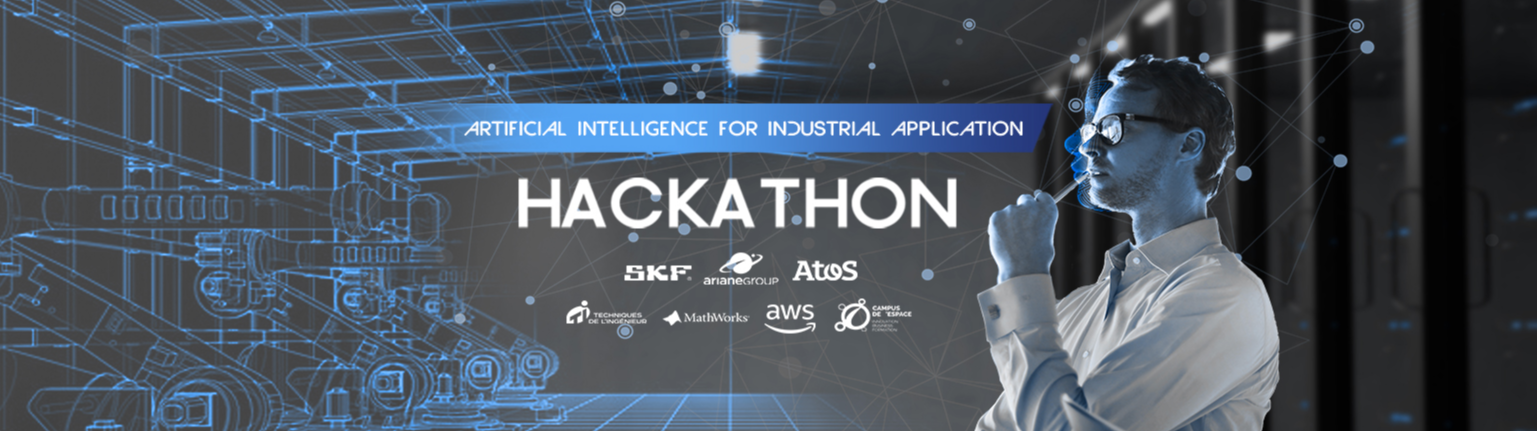

## Introduction

Ce live script est le résumé du projet de l'équipe Taranis pour le hackathon AI4IA. On peut alors décomposer celui-ci en trois grandes parties:

- La première est le chargement des données et l'étude de celles-ci.

- La seconde est la construction du modèle ainsi que son entraînement.

- La troisième est la vérification du modèle à travers les tests de performance.

Ce live script sera volontairement peut fournit en commentaire afin de ne pas surcharger les différentes étapes. Toutes les indications complémentaires (comme la construction du modèle) sont fournies dans le PDF initulé* AI4IA_Taranis.*

## Partie 1: Configuration des données

### a - Chargement du projet

On commence par charger le projet :

proj = openProject("AI4IA_phase1_matlab.prj");

### b - Chargement des données

Puis, à l'aide des fonctions fournies, on charge toutes les données du dossier "DataSet_phase1".

% Chargement sous forme de file datastore
data_fds = fileDatastore(fullfile(prjRootFolder,"data","DataSet_phase1"), "FileExtensions",".csv", "ReadFcn",@readtable, "ReadMode","File"); 

Les 8 documents représentent une série temporelle contenant : 

- Time

- Output1

- Input

- Output2

- Output3

- Output4

- Output5

*Remarque :* Le fichier input7 est un fichier créé qui regroupe les 7 autres séries de données.

On affiche ensuite les données sous leur forme Excel:

preview(data_fds)

ans = 10236×7 table
    Time       Output1      Input    Output2    Output3    Output4    Output5
    _____    ___________    _____    _______    _______    _______    _______

        0    -2.4641e-07      0        0.5        0.5      1.0119     1.0098 
    0.001    -2.4641e-07      0        0.5        0.5      1.0119     1.0098 
    0.002    -2.4641e-07      0        0.5        0.5      1.0119     1.0098 
    0.003    -2.4641e-07      0        0.5        0.5      1.0119     1.0098 
    0.004    -2.4641e-07      0        0.5        0.5      1.0119     1.0098 
    0.005    -2.4641e-07      0        0.5        0.5      1.0119     1.0098 
    0.006    -2.4641e-07      0        0.5        0.5      1.0119     1.0098 
    0.007    -2.4641e-07      0        

On utilise ensuite la fonction `loadDataSet` du package `utilities `pour charger les données sous la forme d'une structure.

data_dir = fullfile(prjRootFolder,"data","DataSet_phase1");
dataStruct = utilities.loadDataSet(data_dir);

### c - Affichage des données

On continue en visualisant toutes les données. Cette étape est très importante car elle permet une meilleure appréhension des données et donc un meilleur raisonnement sur le problème posé (input7 n'est pas affiché car il reprend l'ensemble des autres données).

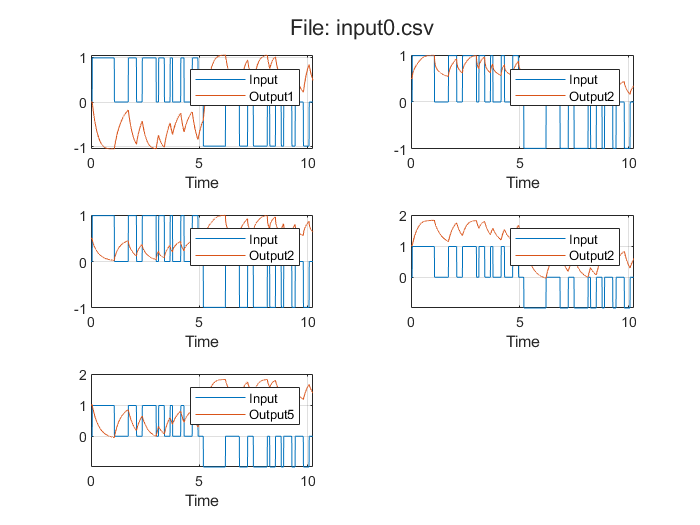

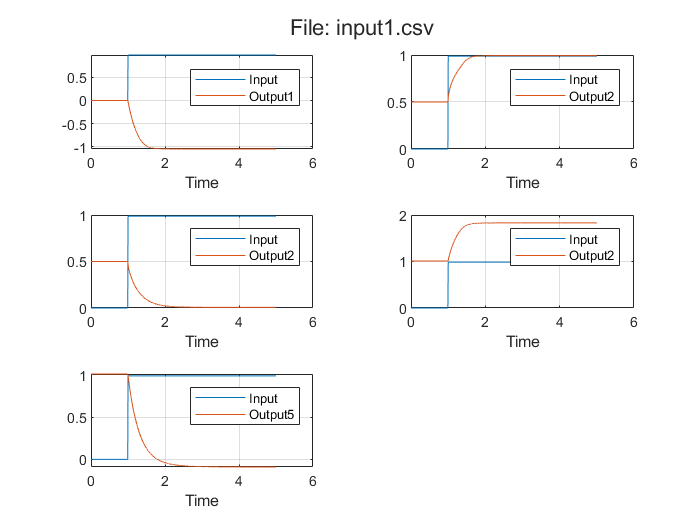

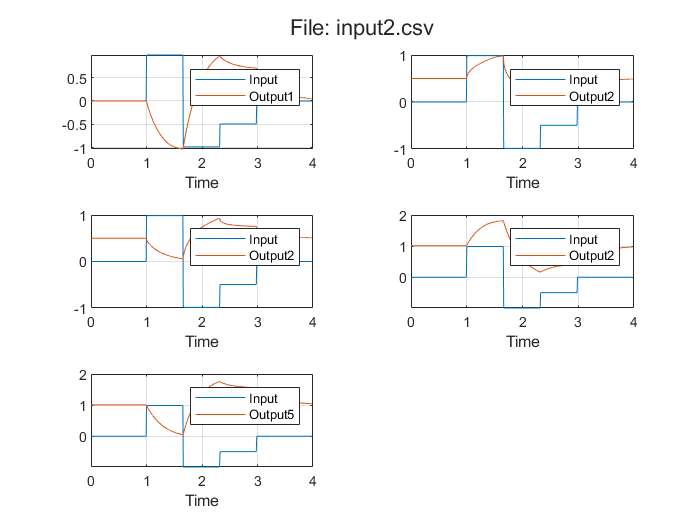

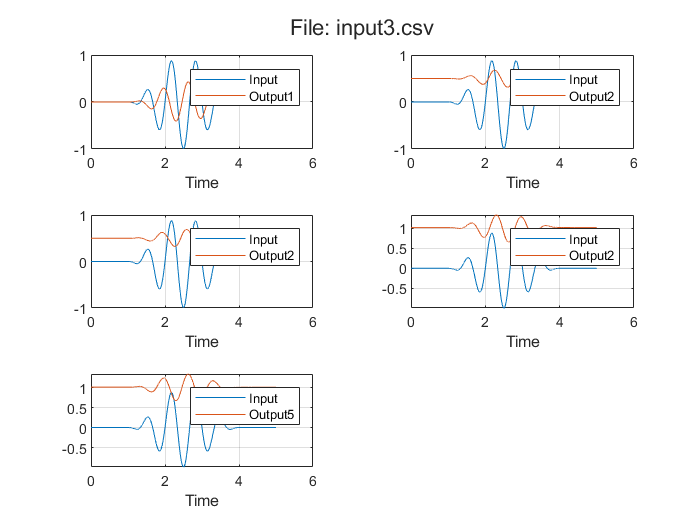

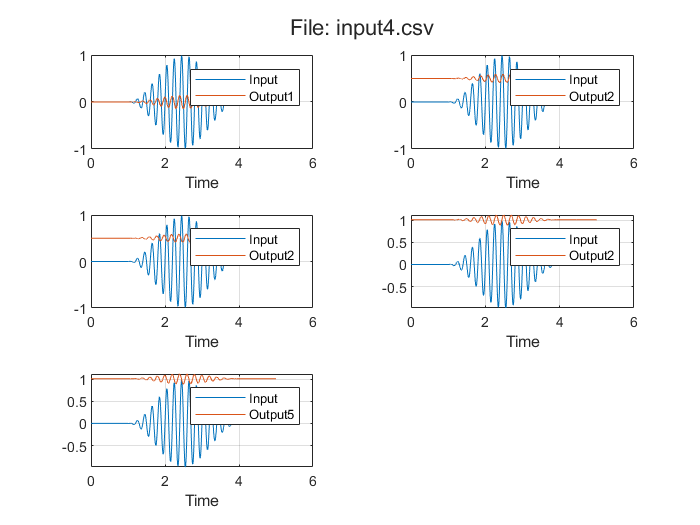

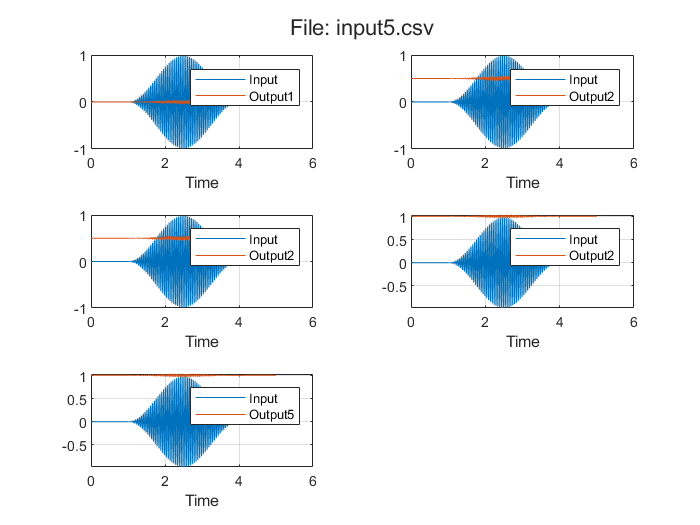

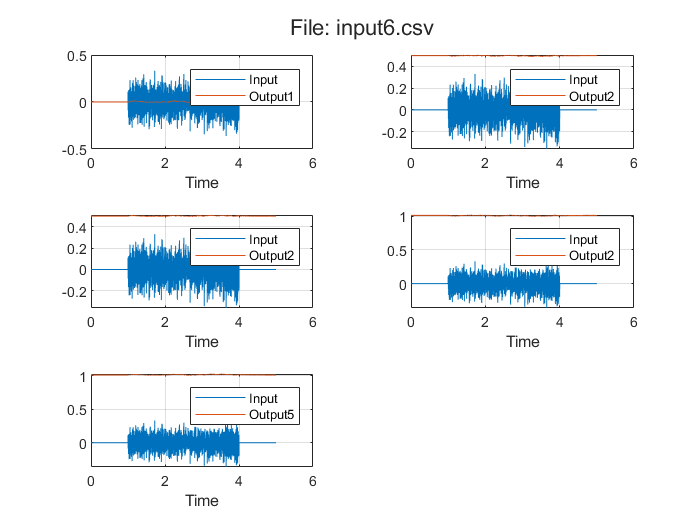

% Visualisation pour chaque fichier
for i=1:numel(dataStruct)-1
    figure
    tlayout=tiledlayout("flow");
    title(tlayout,"File: "+string(dataStruct(i).fname+".csv"))
    
    
    nexttile
    plot(dataStruct(i).data.Time, [dataStruct(i).data.Input, dataStruct(i).data.Output1])
    legend("Input", "Output1")
    xlabel("Time")
    grid on
    
    nexttile
    plot(dataStruct(i).data.Time, [dataStruct(i).data.Input, dataStruct(i).data.Output2])
    legend("Input", "Output2")
    xlabel("Time")
    grid on
    
    nexttile
    plot(dataStruct(i).data.Time, [dataStruct(i).data.Input, dataStruct(i).data.Output3])
    legend("Input", "Output2")
    xlabel("Time")
    grid on
    
    nexttile
    plot(dataStruct(i).data.Time, [dataStruct(i).data.Input, dataStruct(i).data.Output4])
    legend("Input", "Output2")
    xlabel("Time")
    grid on

    nexttile
    plot(dataStruct(i).data.Time, [dataStruct(i).data.Input, dataStruct(i).data.Output5])
    legend("Input", "Output5")
    xlabel("Time")
    grid on
    
end

## Partie 2: Modèle d'apprentissage

### a - Choix des données

Dans cette seconde partie, on commence par sélectionner les données avec lesquelles on souhaite entraîner le modèle. Dans notre cas, la méthode la plus efficace semble d'entraîner le modèle avec toutes les données fournies, on utilise donc l'input7.

Pour les validations, on utilisera arbitrairement input2.

trainingFile_index = 7;
validationFile_index = 2;

dataStruct_t_x_y = utilities.loadDataSetAs_t_x_y(data_dir);

% Données d'entrainement
disp("Données d'entrainement: '" + string(dataStruct_t_x_y(trainingFile_index+1).fname)+"'.csv")

Données d'entrainement: 'input7'.csv


t_train = dataStruct_t_x_y(trainingFile_index).t; % time
x_train = dataStruct_t_x_y(trainingFile_index).x; % inputs
y_train = dataStruct_t_x_y(trainingFile_index).y; % targets

Dans cet exemple pour des raisons de commodités les données d'entraînement seront sous échantillonnés avec 1 point tous les "nDecim" pas de temps (comme donnée dans l'énoncé du projet).

% sous échantillonage : 1 point tous les "nDecim" pas de temps
nTot = height(t_train);
nStart = 1;
nDecim = 10;
idx = nStart:nDecim:nTot;

t_train = t_train(idx,:);
x_train = x_train(idx,:);
y_train = y_train(idx,:);

% Données de test
disp("Données de test: '" + string(dataStruct_t_x_y(validationFile_index+1).fname)+"'.csv")

Données de test: 'input2'.csv


t_test = dataStruct_t_x_y(validationFile_index).t; % time
x_test = dataStruct_t_x_y(validationFile_index).x; % inputs
y_test = dataStruct_t_x_y(validationFile_index).y; % targets

### b - Construction du modèle

On commence par calculer la taille de l'entrée et de la sortie des données d'entraînement:

nInputs  = size(x_train,2);
nOutputs = size(y_train,2);

On continue par définir la structure du modèle. Pour les explications sur sa construction, veuillez lire le PDF ci-joint.

layers = [
    sequenceInputLayer(nInputs,"Name","sequenceinput")
    gruLayer(100,"Name","gru_1")
    fullyConnectedLayer(nOutputs,"Name","fc")
    regressionLayer("Name","regressionoutput")];

Sous forme de graphe, l'architecture du réseau est la suivante:

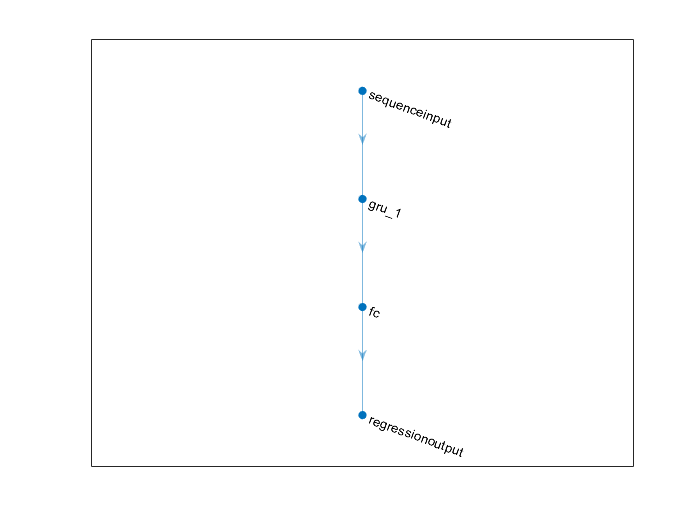

figure
plot(layerGraph(layers))

On finit par définir les paramètres d'apprentissage du modèle:

% definition des paramètres d'apprentissage
options = trainingOptions('sgdm', ...
    'LearnRateSchedule','none', ...
    "InitialLearnRate",0.00002, ...
    'MaxEpochs',20000, ...
    'MiniBatchSize',64, ...
    "ExecutionEnvironment","auto",...
    'Plots','training-progress');

### c - Entrainement du réseau

Dans cette partie, on se contente d'entraîner le réseau avec les données fournies ci-dessus.

Training on single GPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:02 |         1.60 |          1.3 |      2.0000e-05 |
|      50 |          50 |       00:00:04 |         0.10 |      4.8e-03 |      2.0000e-05 |
|     100 |         100 |       00:00:05 |         0.08 |      3.3e-03 |      2.0000e-05 |
|     150 |         150 |       00:00:07 |         0.08 |      3.3e-03 |      2.0000e-05 |
|     200 |         200 |       00:00:09 |         0.08 |      3.3e-03 |      2.0000e-05 |
|     250 |         250 |       00:00:10 |         0.08 |      3.3e-03 |      2.0000e-05 |
|     300 |         300 |       00:00:12 |         0.08 |      3.3

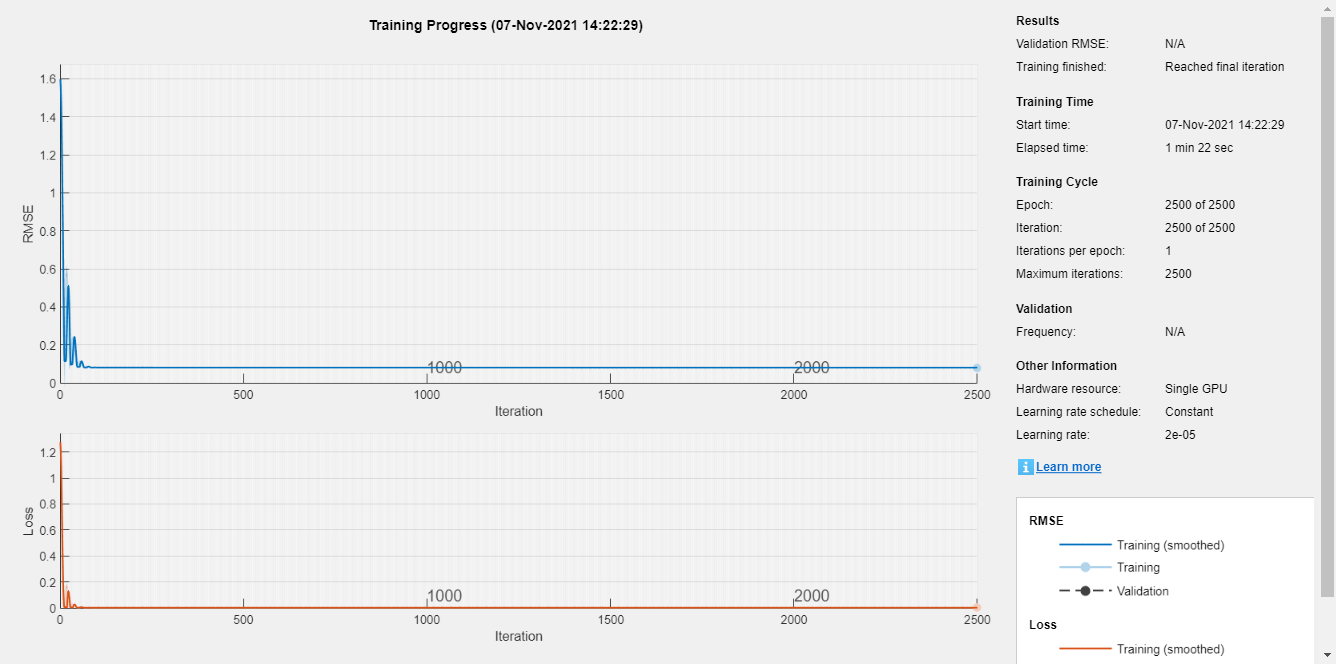

[net, trainingprocessinfo] = trainNetwork(x_train', y_train',layers,options);

### d - Prédiction sur les données

Une fois le modèle entraîné, on peut à présent réaliser des prédictions pour les comparer avec les données déjà existantes.

On commence donc par prédire les données d'entraînement:

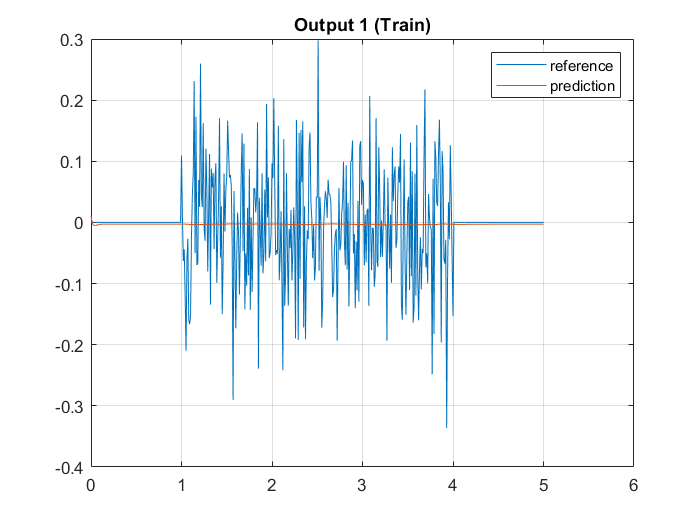

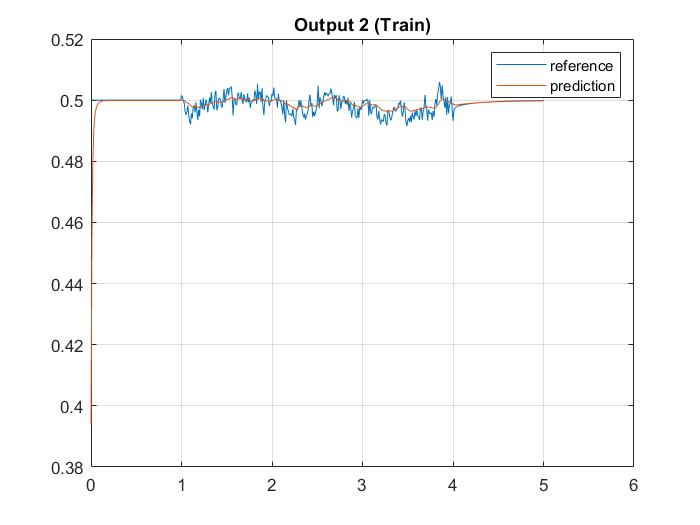

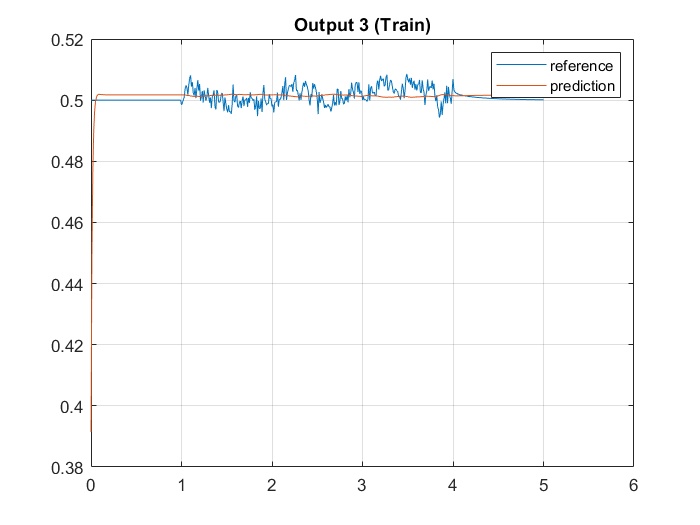

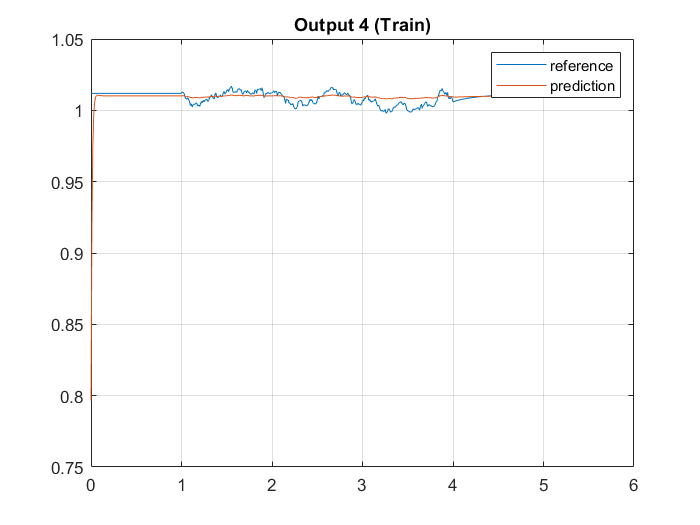

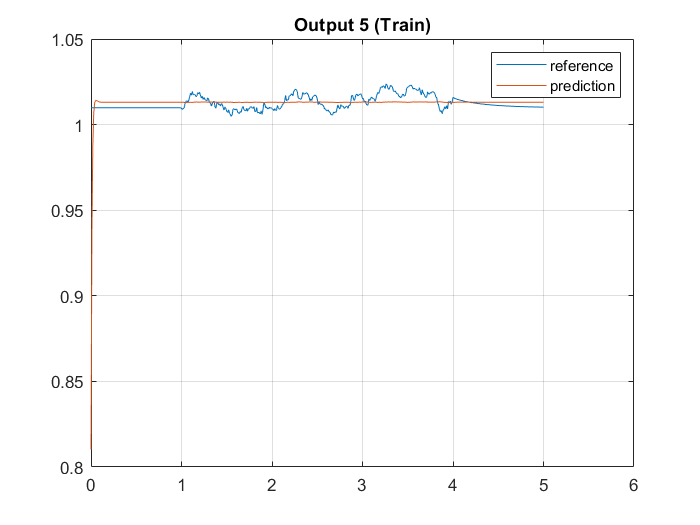

y_pred = predict(net, x_train');
y_pred = y_pred.';

for i=1:nOutputs
    figure
    plot(t_train, y_train(:,i), "DisplayName","reference")
    hold on
    plot(t_train, y_pred(:,i)', "DisplayName","prediction")
    hold off
    legend()
    grid on
    title("Output "+string(i)+" (Train)")
end

On prédit ensuite les données de test:

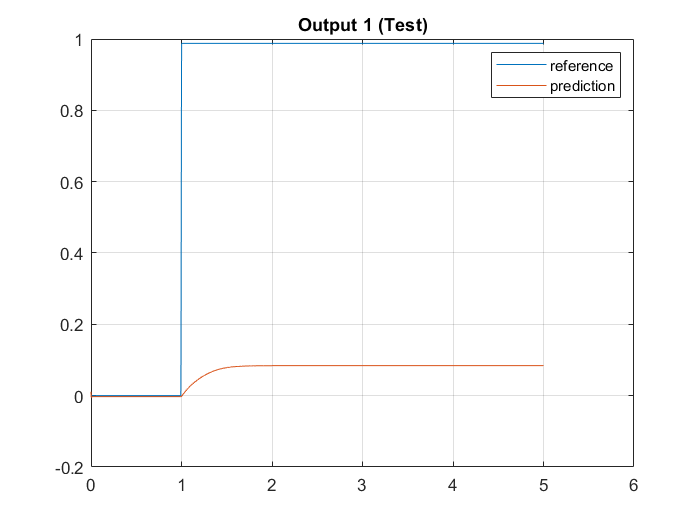

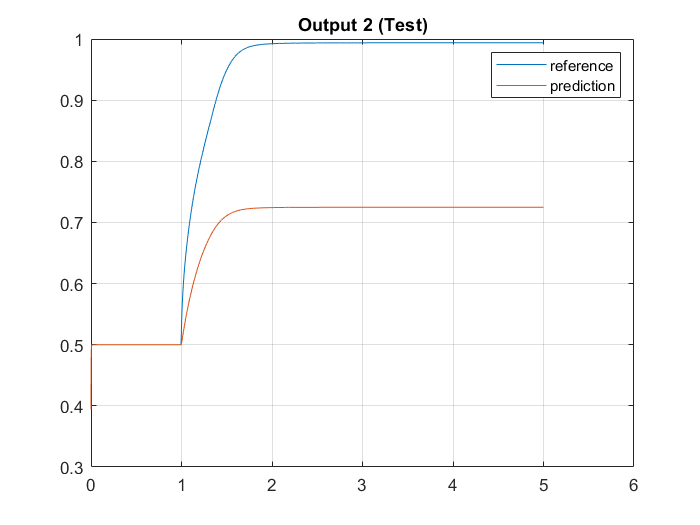

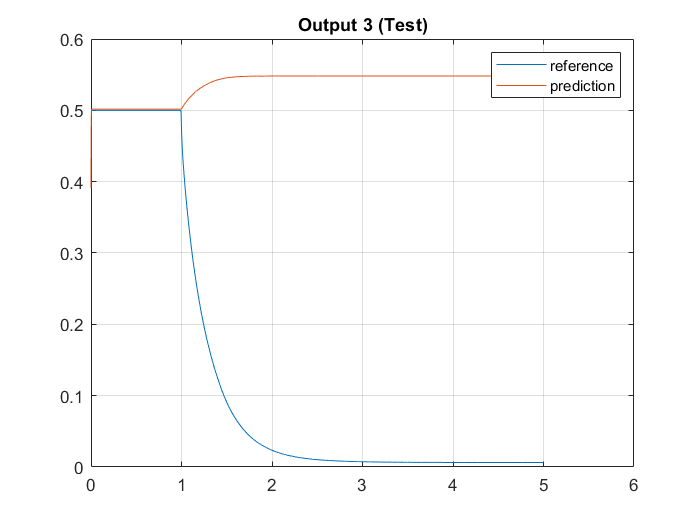

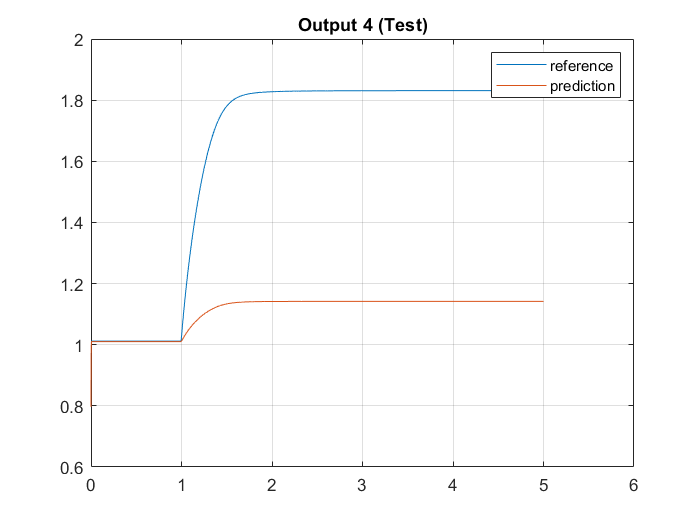

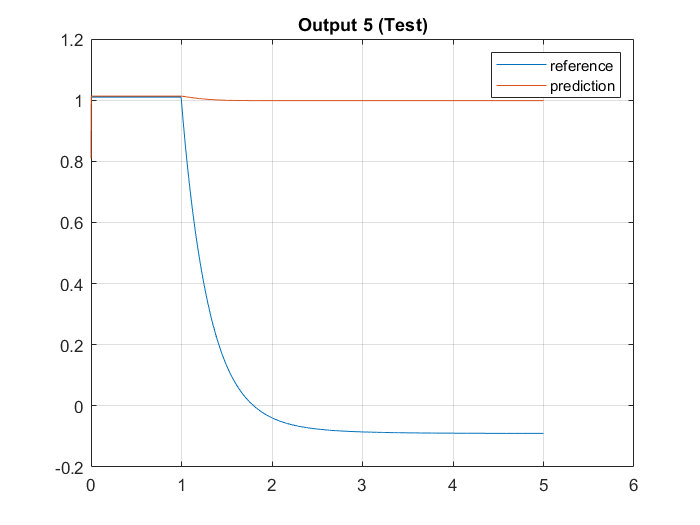

% Predictions sur les données de test
y_pred = predict(net, x_test');
y_pred = y_pred.';

for i=1:nOutputs
    figure
    plot(t_test, y_test(:,i), "DisplayName","reference")
    hold on
    plot(t_test, y_pred(:,i), "DisplayName","prediction")
    hold off
    legend()
    grid on
    title("Output "+string(i)+" (Test)")
end

On sauvegarde ensuite le modèle résultat à l'endroit prévu.

save(fullfile(prjRootFolder,"src", "exampleModelDirectory", "exampleModel.mat"), "net");

## Partie 3: Test du modèle

### a - Test rapide

A présent que l'on a créé le modèle, on peut le charger sous la forme de la structure précédemment sauvegardée :

exampleTrainedModelStruct = load(fullfile(prjRootFolder,"src", "exampleModelDirectory", "exampleModel.mat"));

Maintenant que le modèle est chargé, il faut pouvoir le tester. Pour cela, on utilise `runAI4IATests (`d'abord en test rapide)`:`

AI4IAtestsOptions= "doOnlyQuickTests";
runAI4IATests(exampleTrainedModelStruct,AI4IAtestsOptions)      

Tous les tests sont passés, il faut donc maintenant réaliser un test complet.

### b - Test complet

Dans cette seconde partie, on réalise un test complet du modèle afin de s'assurer de sa pertinence: 

AI4IAtestsOptions = "doFullTests";

Using as Model API function <description>, the file located at following path:
##### C:\Users\Dubou\Downloads\AI4IA_phase1_matlab_v2b\src\exampleModelDirectory\description.m
 
Using as Model API function <fit>, the file located at following path:
##### C:\Users\Dubou\Downloads\AI4IA_phase1_matlab_v2b\src\exampleModelDirectory\fit.m
 
Using as Model API function <predict_timeseries>, the file located at following path:
##### C:\Users\Dubou\Downloads\AI4IA_phase1_matlab_v2b\src\exampleModelDirectory\predict_timeseries.m
 
runAI4IATests: doing only quick tests
Running ModelAPITest
......
Done ModelAPITest
__________

  1×6 TestResult array with properties:

    Name
    Passed
    Failed
    Incomplete
    Duration
    Details

Totals:
   6 Passed, 0 Failed, 0 Incomplete.
   0.81708 seconds testing time.



runAI4IATests(exampleTrainedModelStruct,AI4IAtestsOptions);

Le test complet fonctionne bien, on peut donc passer au calcul des performances.

### b - Performances du modèle 

La dernière étape est d'implémenter le code permettant de tester la performance du modèle. Comme dans le précédent entrainement, on entraine le modèle sur l'ensemble des données puis on lui les fait vérifier sur l'input2.

Using as Model API function <description>, the file located at following path:
##### C:\Users\Dubou\Downloads\AI4IA_phase1_matlab_v2b\src\exampleModelDirectory\description.m
 
Using as Model API function <fit>, the file located at following path:
##### C:\Users\Dubou\Downloads\AI4IA_phase1_matlab_v2b\src\exampleModelDirectory\fit.m
 
Using as Model API function <predict_timeseries>, the file located at following path:
##### C:\Users\Dubou\Downloads\AI4IA_phase1_matlab_v2b\src\exampleModelDirectory\predict_timeseries.m
 
Running ModelAPITest


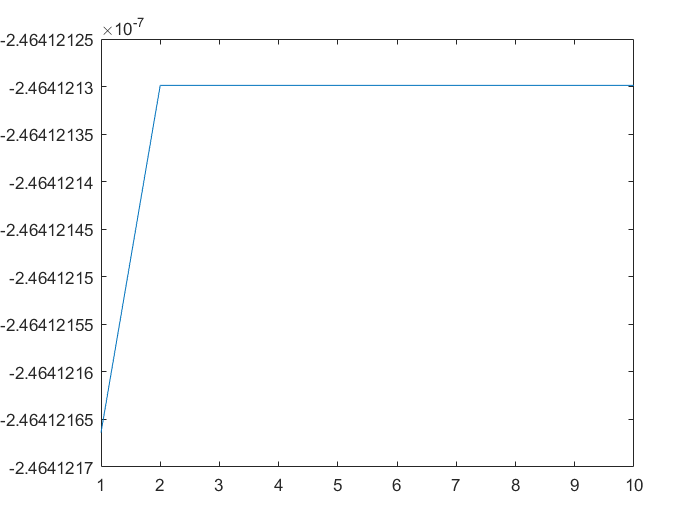

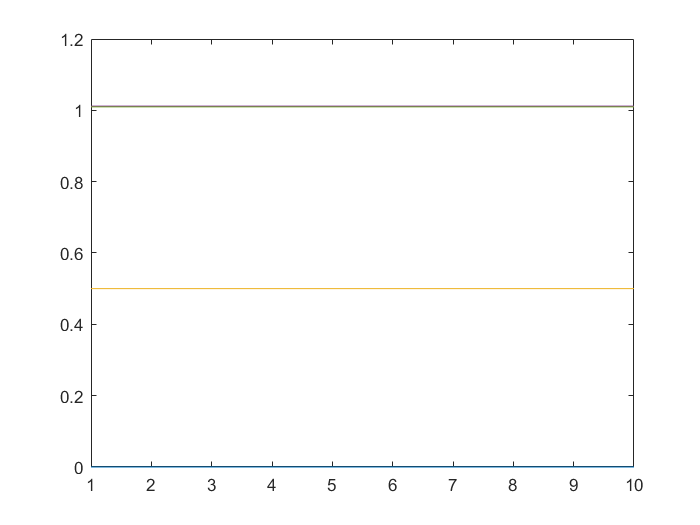

Training on single GPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:02 |         1.59 |          1.3 |      2.0000e-05 |
|      50 |          50 |       00:00:02 |         1.29 |          0.8 |      2.0000e-05 |
|     100 |         100 |       00:00:03 |         0.97 |          0.5 |      2.0000e-05 |
|     150 |         150 |       00:00:04 |         0.73 |          0.3 |      2.0000e-05 |
|     200 |         200 |       00:00:04 |         0.54 |          0.1 |      2.0000e-05 |
|     250 |         250 |       00:00:05 |         0.41 |      8.5e-02 |      2.0000e-05 |
|     300 |         300 |       00:00:05 |         0.32 |      5.2

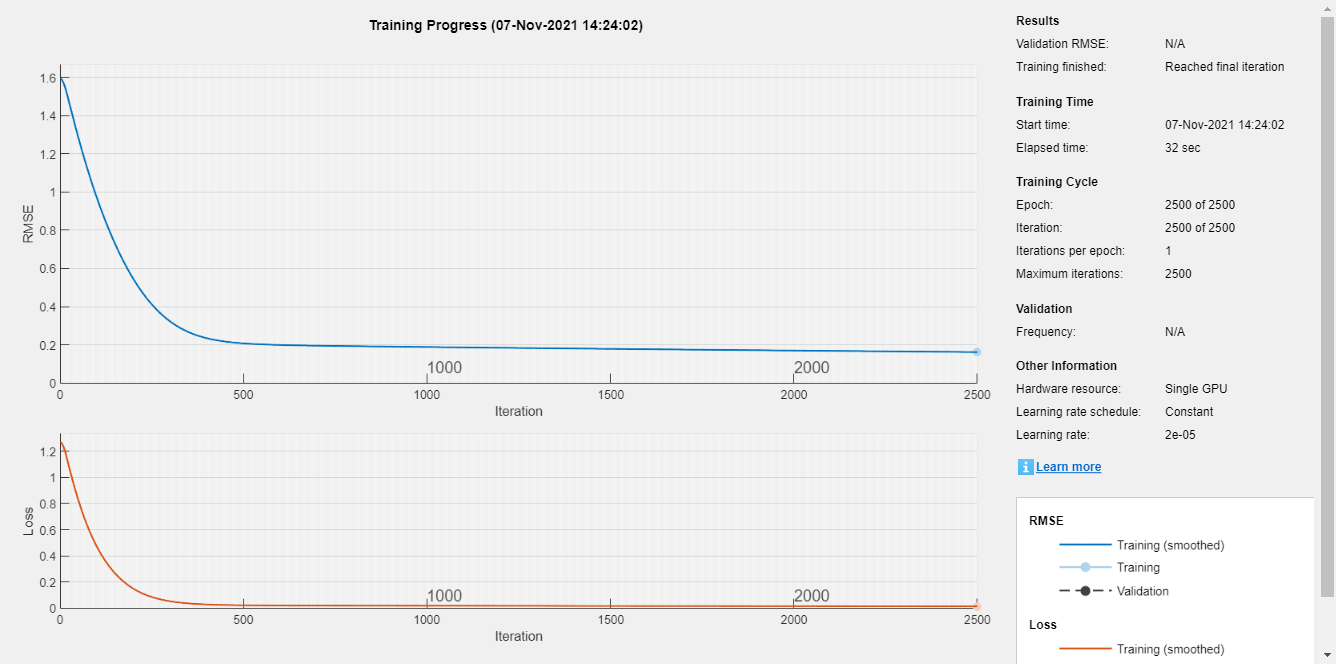

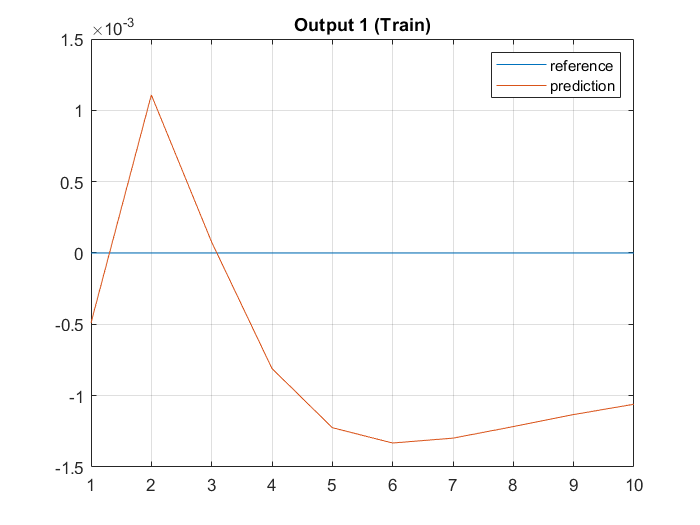

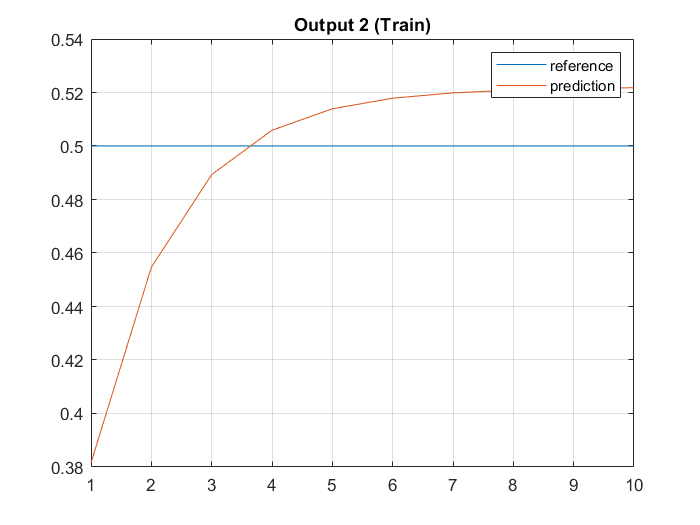

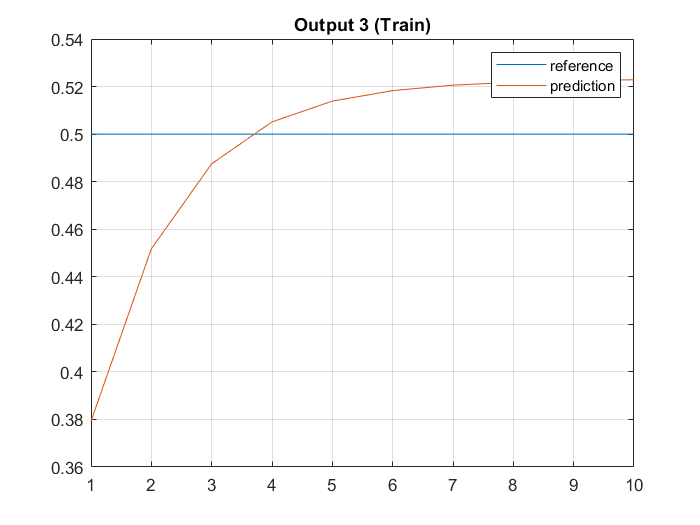

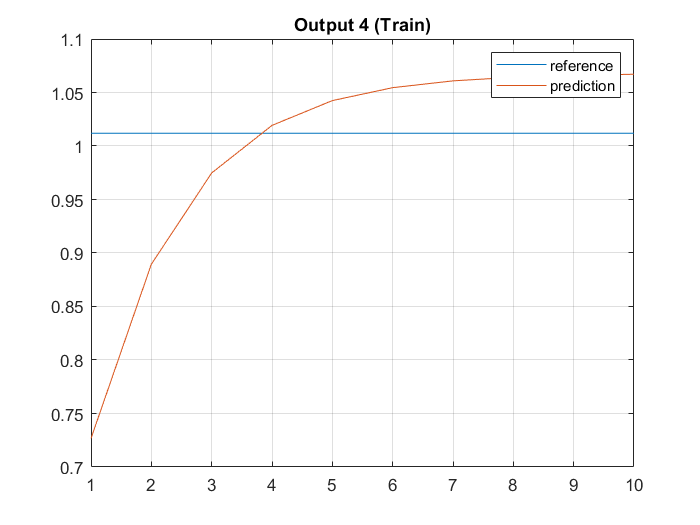

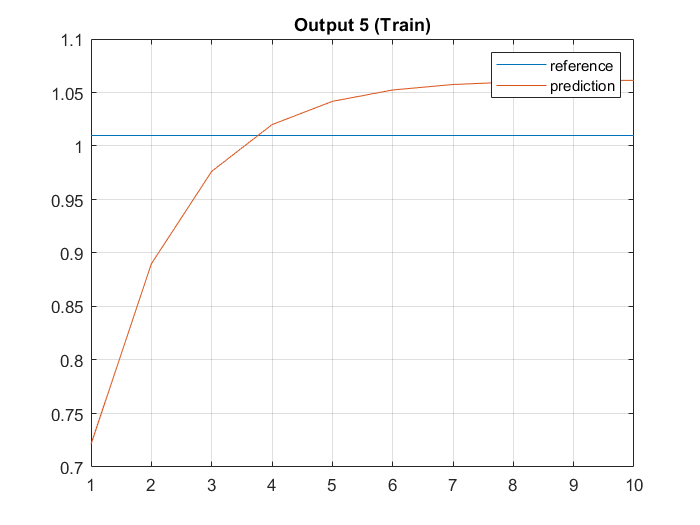

.......
Done ModelAPITest
__________

  1×7 TestResult array with properties:

    Name
    Passed
    Failed
    Incomplete
    Duration
    Details

Totals:
   7 Passed, 0 Failed, 0 Incomplete.
   36.551 seconds testing time.



data_dir = fullfile(prjRootFolder, "data", "DataSet_phase1");
test_filename   = "input2"

train_fileName  = "input7"
output_dir =  fullfile(prjRootFolder, "metrics_results");
utilities.metrics.calc_metrics(train_fileName, data_dir, test_filename, output_dir)

test_filename = "input2"

train_fileName = "input7"

Training on single GPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:01 |         1.80 |          1.6 |      2.0000e-06 |
|      50 |          50 |       00:01:15 |         0.35 |      6.2e-02 |      2.0000e-06 |
|     100 |         100 |       00:02:32 |         0.35 |      6.0e-02 |      2.0000e-06 |
